# MECH 6V29 - HW 4

Author: Jonas Wagner

Date: 2022-03-22

clear
clc
close all

## Problem 4

Draw a Gabriel graph induced by the following set of 14 points.

P = [
    1 2 3 4 5 6 7 8 9 10 11 12 13 14
    9 7 14 9 12 6 6 12 1 1 2 5 12 12
    ];
X = P(1,:)';
Y = P(2,:)';

#### Plot Point Locations

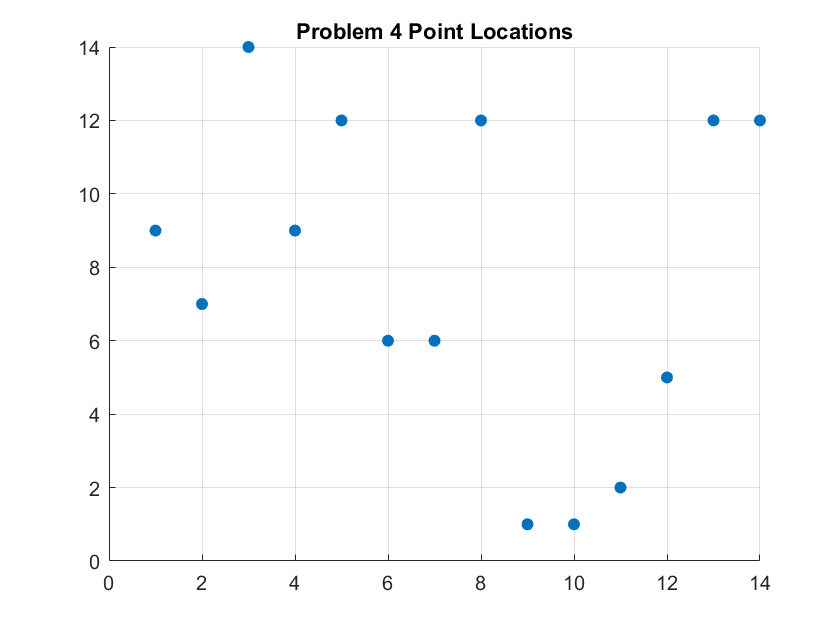

figure();
scatter(X, Y, 'filled')
title('Problem 4 Point Locations')
grid on
saveas(gcf, '.\fig\pblm4_points.png')

V = num2cell([X Y],2)

V = 14×1 cell array
    {[  1 9]}
    {[  2 7]}
    {[ 3 14]}
    {[  4 9]}
    {[ 5 12]}
    {[  6 6]}
    {[  7 6]}
    {[ 8 12]}
    {[  9 1]}
    {[ 10 1]}
    {[ 11 2]}
    {[ 12 5]}
    {[13 12]}
    {[14 12]}


### Determine Gabriel Graph

idx_edge = 1;
tol_gabriel = 0.01;
for i = 1:size(V,1)
    for j = 1:size(V,1)

#### Generate Midpoints

        M{i,j}(1) = (X(i) + X(j))/2;
        M{i,j}(2) = (Y(i) + Y(j))/2;
        M_dist{i,j} = norm(M{i,j} - V{i});
        

#### Determine Edges

        if i ~= j
            for k = 1: size(V,1)
                if k == i || k == j
                    in_circle(i,j,k) = 0;
                else
                    in_circle(i,j,k) = norm(M{i,j} - V{k}) < M_dist{i,j} + tol_gabriel;
                end
            end
            if any(in_circle(i,j,:) == 1,'all')
                continue
            else
                E{idx_edge} = [i, j];
                idx_edge = idx_edge + 1;
                continue
            end
        end
    end
end

#### Gabriel Graph Edges

E = E'

E = 40×1 cell array
    {[1 2]}
    {[1 3]}
    {[1 4]}
    {[2 1]}
    {[2 4]}
    {[2 6]}
    {[3 1]}
    {[3 5]}
    {[4 1]}
    {[4 2]}
    {[4 5]}
    {[4 6]}
    {[5 3]}
    {[5 4]}
    {[5 8]}
    {[6 2]}


### Plot Graph

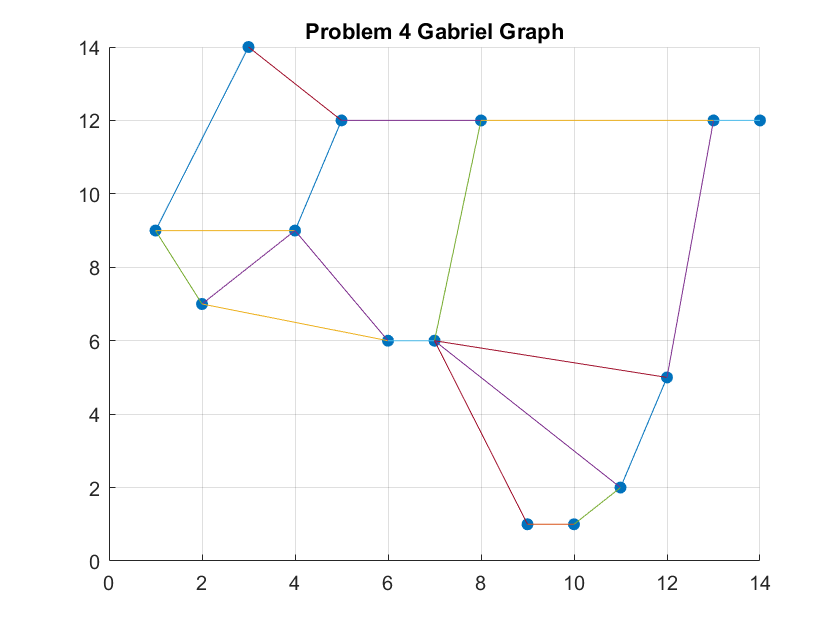

fig_pblm4_resutls = plot_graph(V, E);
saveas(fig_pblm4_resutls, '.\fig\pblm4_results.png')

## Export to PDF automatically

export("MECH6V29_HW04");